# **Sygnals and Systems - Dr. Akhavan**

## CA6 - Matin Bazrafshan

# Part 1

First we define the hyperparameters of the problem.

clearvars;
alpha = 0.5;
beta = 0.3;
fs = 100;
ts = 1 / fs;
C = 3e8;
tstart = 0;
tend = 1;
t = tstart : ts : tend - ts;
T = tend - tstart;

### 1.1 Plot sent signal

sent signal is $x\left(t\right)=\mathrm{cos}\left(2\pi f_c t\right)$

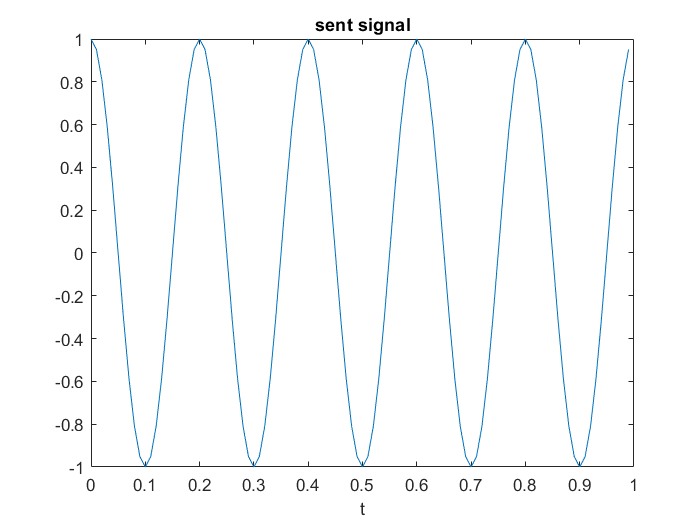

fc = 5;
x = cos(2 * pi * fc * t);
plot(t, x);
xlabel('t');
title('sent signal');

### 1.2 Plot received signal

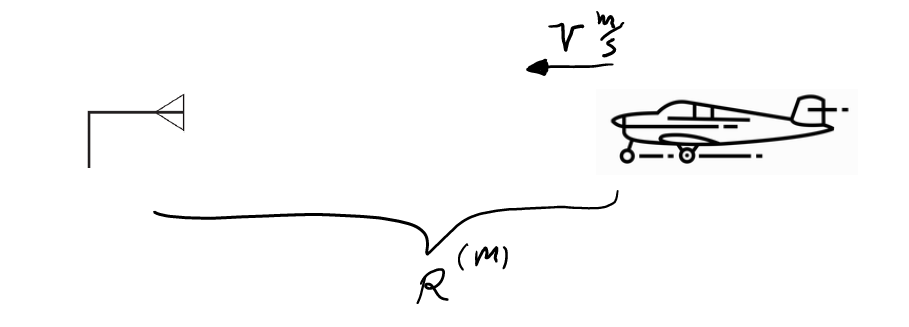

received signal is $\mathrm{𝑦}\left(\mathrm{𝑡}\right)=\mathrm{𝛼}\;\mathrm{cos}\left(2\mathrm{𝜋}\left(\mathrm{𝑓𝑐}+\mathrm{𝑓𝑑}\right)\left(\mathrm{𝑡}-\mathrm{𝑡𝑑}\right)\right)$where $f_d$ is doppler frequency and $t_d$ is delay time. also we know:

-  $f_d =\beta V$where $\beta$ is a constant and $V$ is speed.

- $t_d \;=\frac{2}{C}R$ where $C$ is light speed($~3\mathrm{e8}$) and $R$ is distance.

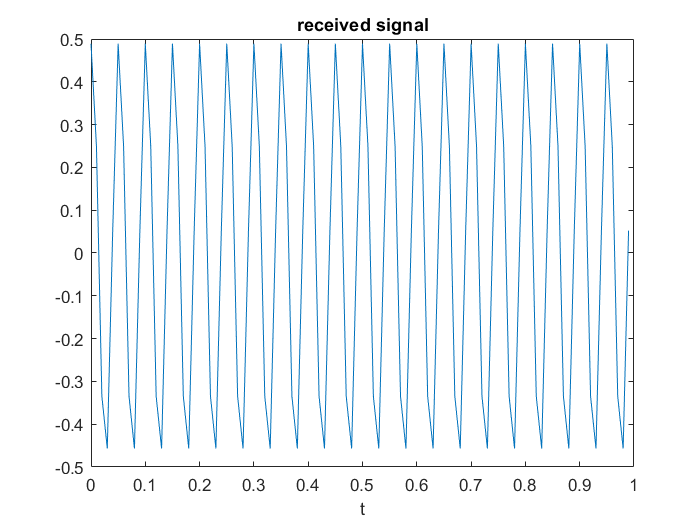

V = 180 / 3.6;
R = 250 * 1000;
td = 2 / C * R;
fd = beta * V;
y = alpha * cos(2 * pi * (fc + fd) * (t - td));
plot(t, y);
xlabel('t');
title('received signal');

### 1.3 Fourier-transform of received signal


$$y\left(t\right)=\alpha \;\mathrm{cos}\left(2\pi \left(f_c +f_c \right)\left(t-t_d \right)\right)\Rightarrow \alpha \;\mathrm{cos}\left(2\pi \left(f_c +f_c \right)t-2\pi \left(f_c +f_c \right)t_d \right)\Rightarrow \alpha \;\mathrm{cos}\left(2\pi \;f_{\mathrm{new}} t+\varphi_{\mathrm{new}} \right)$$


so if we apply fourier transform: $\mathcal{F}\left(y\left(t\right)\right)=\hat{y} \left(w\right)\;=\pi \delta \left(\omega -f_{\mathrm{new}} \right)e^{-\mathrm{jw}\varphi_{\mathrm{new}} } +\pi \delta \left(\omega +f_{\mathrm{new}} \right)e^{\mathrm{jw}\varphi_{\mathrm{new}} }$ now by having measuring absolute value of $\hat{y} \left(w\right)$ we can calculate $f_{\mathrm{new}}$ and then $f_d$ and by measuring phase of $\hat{y} \left(w\right)$ we can calculate $\varphi_{\mathrm{new}}$ and then $t_d$. 

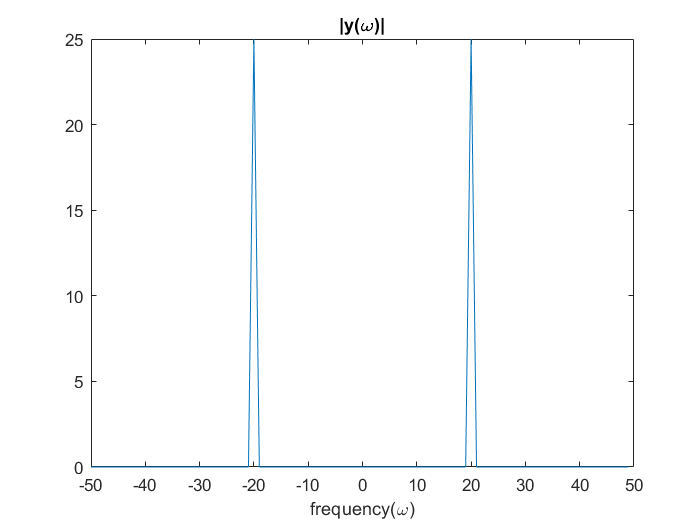

N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
y_fourier = fftshift(fft(y));

plot(f, abs(y_fourier));
xlabel('frequency(\omega)');
title('|y(\omega)|')

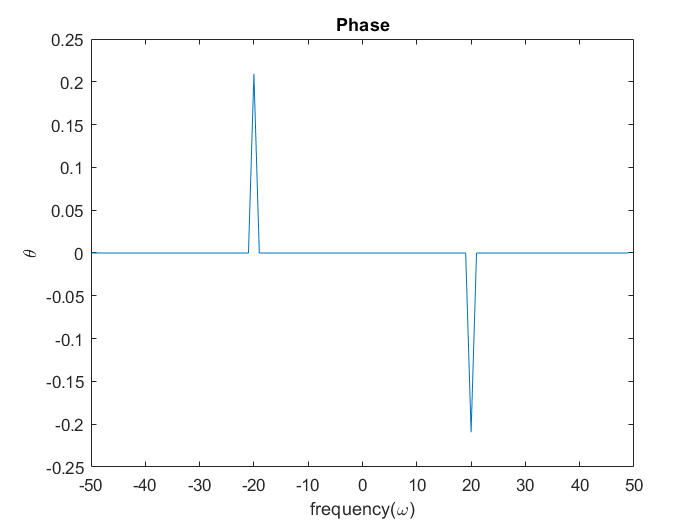

threshold = 1e-6;
y = alpha * cos(2 * pi * (fc + fd) * (t - td));
y_fourier = fftshift(fft(y));
y2 = y_fourier;
y2(abs(y2) < threshold) = 0;
theta = angle(y2);
plot(f, theta);
xlabel('frequency(\omega)')
ylabel('\theta')
title('Phase')

Result can be seen:

[fd_estimated, td_estimated] = get_fd_td(y_fourier, fc, f)

fd_estimated = 15

td_estimated = 0.0017

V_estimated = fd_estimated / beta;
fprintf('Estimated V is %.1f m/s and %.1f Km/H', V_estimated, V_estimated * 3.6);

Estimated V is 50.0 m/s and 180.0 Km/H

R_estimated = td_estimated * C / 2;
fprintf('Estimated R is %.1f Km', R_estimated / 1000);

Estimated R is 250.0 Km

### 1.4 Adding noise

We can see, $t_d$ is very sensitive to noise, so the distance's error grows with a big rate over time. On the other hand $f_d$ is more resistant against noise and speed has much less error than distance.

times = 100;
fd_mean = 0;
td_mean = 0;

Rs_estimated = [];
Vs_estimated = [];

for std = 0:0.05:0.7
    fd_mean = 0;
    td_mean = 0;
    for i = 1:times
        y_noisy = std * randn(size(y_fourier)) + y;
        y_fourier_noisy = fftshift(fft(y_noisy));
        [fd_estimated, td_estimated] = get_fd_td(y_fourier_noisy, fc, f);
        fd_mean = fd_mean + fd_estimated / times;
        td_mean = td_mean + td_estimated / times;
    end
    V_estimated = fd_mean / beta;
    R_estimated = td_mean * C / 2;
    Rs_estimated = [Rs_estimated, R_estimated];
    Vs_estimated = [Vs_estimated, V_estimated];
    fprintf("std: %.1f, R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", std, R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

std: 0.0, R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.1, R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.1, R: 249.2 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.2, R: 252.4 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.2, R: 250.2 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.3, R: 249.7 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.3, R: 256.4 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.4, R: 251.8 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.4, R: 242.1 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.5, R: 255.5 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.5, R: 248.2 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.6, R: 269.1 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.6, R: 295.9 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.7, R: 281.5 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.7, R: 503.2 Km, V: 49.2 m/s, V: 177.0 Km/H 


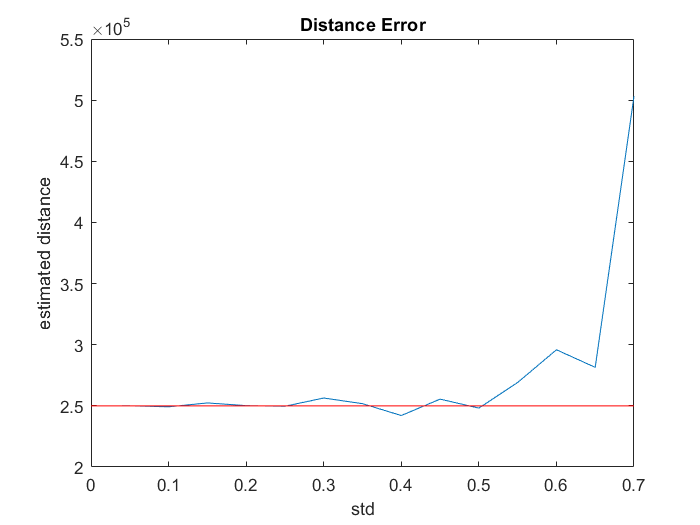

plot(0:0.05:0.7, Rs_estimated);
hold on;
plot([0,0.7], [250000, 250000], 'Color', 'r');
hold off;
xlabel('std');
ylabel('estimated distance');
title('Distance Error');

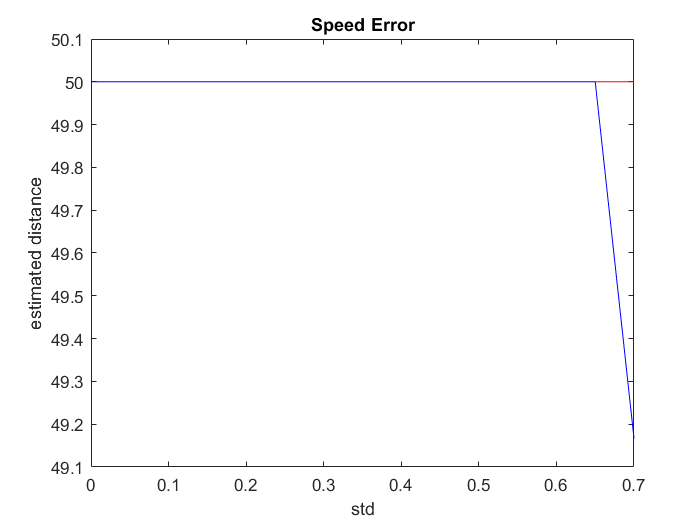

plot([0,0.7], [50, 50], 'Color', 'r');
hold on;
plot(0:0.05:0.7, Vs_estimated, 'Color', 'b');
hold off;
xlabel('std');
ylabel('estimated distance');
title('Speed Error');

### 1.5 Detecting multiple objects

To do this, we just need to detect unique picks as many as number of objects.

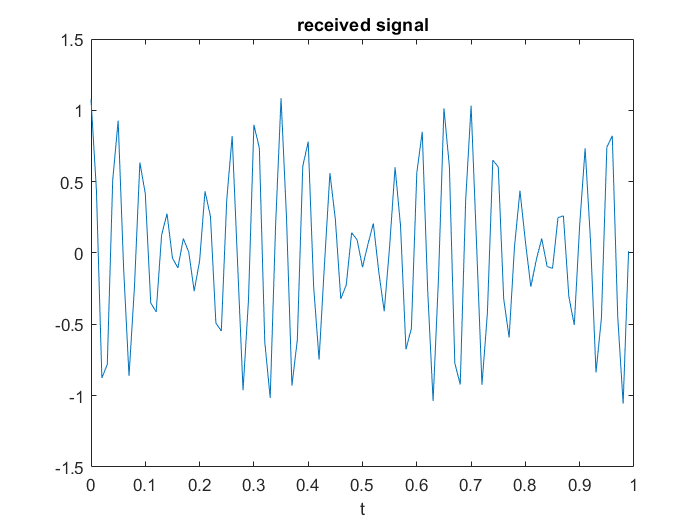

V1 = 180 / 3.6;
R1 = 250 * 1000;
td1 = 2 / C * R1;
fd1 = beta * V1;
alpha1 = 0.5;
y1 = alpha1 * cos(2 * pi * (fc + fd1) * (t - td1));

V2 = 216 / 3.6;
R2 = 200 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));
y_sum = y1 + y2;
plot(t, y_sum);
xlabel('t');
title('received signal');

### 1.6 Fourier-transform of multiple signals

 It is hard to distinguish signals in plot, but when we switch to fourier space, we can see picks perfectly.

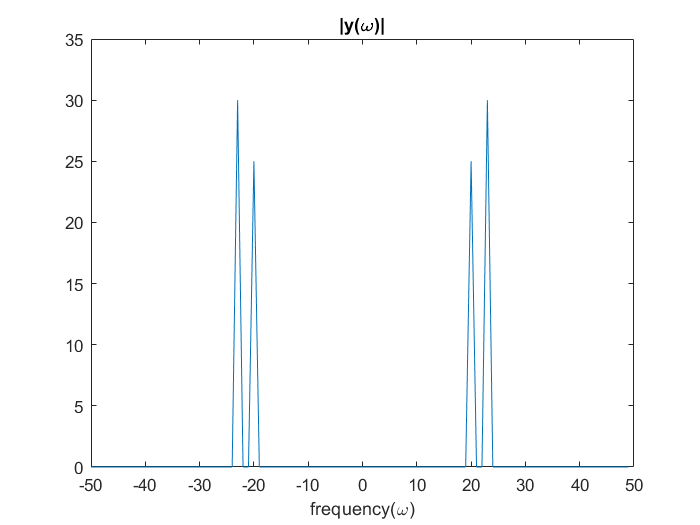

N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
y_fourier_sum = fftshift(fft(y_sum));

plot(f, abs(y_fourier_sum));
xlabel('frequency(\omega)');
title('|y(\omega)|')

We just need to sort picks and choose first `n_signals` unique picks(as each pick will be repeated 2 times, we choose first and skip the second one).

n_signlas = 2;
[fds, tds] = get_fd_td_many(y_fourier_sum, fc, f, 2);
for i = 1:n_signlas
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

R: 200.0 Km, V: 60.0 m/s, V: 216.0 Km/H 
R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 


### 1.7 Two objects with same speed

if the two objects have the same speed, they will have same $f_d$ so their picks happens in one single frequency and the signals can not be distinguished, so we can not detect them and seperate them.

The minimum difference between two object's speeds must be enough to make their picks frequency diferrence bigger than resolution requency so that we will be able to seperate them, so ${|\mathrm{fd}}_1 -{\mathrm{fd}}_2 |>\delta_f$ where $\delta_f$ is frequency resolution. And according to $f_d =\beta V$ we can say ${\left|\beta V\right.}_1 -{\beta V}_2 \left|>\delta_f \right.$  so we can say $|V_1 -\;V_2 |>\frac{\delta_f }{\beta }$.  

V1 = 180 / 3.6;
R1 = 250 * 1000;
td1 = 2 / C * R1;
fd1 = beta * V1;
alpha1 = 0.5;
y1 = alpha1 * cos(2 * pi * (fc + fd1) * (t - td1));

V2 = 180 / 3.6;
R2 = 200 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));
y_sum = y1 + y2;

N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
y_fourier_sum = fftshift(fft(y_sum));

n_signlas = 2;
[fds, tds] = get_fd_td_many(y_fourier_sum, fc, f, 2);
for i = 1:n_signlas
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6); 
end

R: 222.7 Km, V: 50.0 m/s, V: 180.0 Km/H 
R: 3254.4 Km, V: 40.0 m/s, V: 144.0 Km/H 


### 1.8 detecting objects with same distance

if the two objects have the same distance but different speed, they will have different $f_d$ so the picks will be seperated. After finding picks, we can look for the phase at that frequency. Having same distance will result in having sam $t_d$ but that does not make any problem in detecting objects(due to seperate picks.)

V1 = 180 / 3.6;
R1 = 250 * 1000;
td1 = 2 / C * R1;
fd1 = beta * V1;
alpha1 = 0.5;
y1 = alpha1 * cos(2 * pi * (fc + fd1) * (t - td1));

V2 = 216 / 3.6;
R2 = 250 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));
y_sum = y1 + y2;

N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
y_fourier_sum = fftshift(fft(y_sum));

n_signlas = 2;
[fds, tds] = get_fd_td_many(y_fourier_sum, fc, f, 2);
for i = 1:n_signlas
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6);  
end

R: 250.0 Km, V: 60.0 m/s, V: 216.0 Km/H 
R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 


### 1.9 Detect uknown amount of signals

In the situtation which we do not know number of signals, we can apply fourier transform to our received signal then measure number of picks and then divide by 2. The result will be same as number of signals. It is important to apply a reasonable and proper threshold for our picks, because the signal can be noisy, even in the ideal situation, the computer, keeps ~0 for 0-valued fourier-transform signal. So it can misdetect picks. 

I consider threshold = 0.1 in this case.

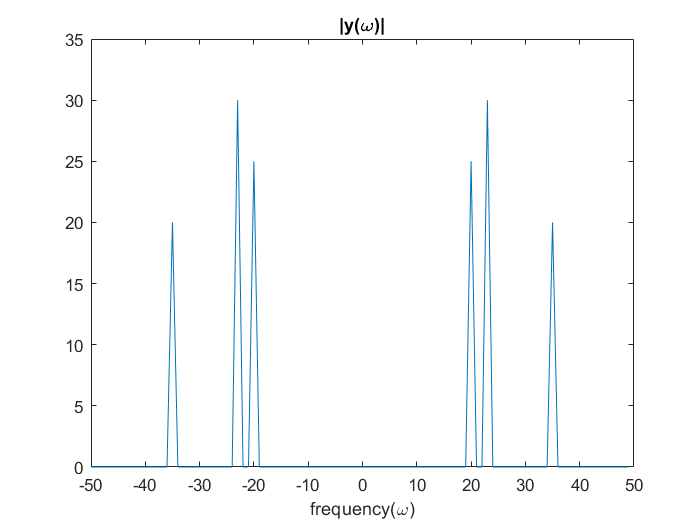

V1 = 180 / 3.6;
R1 = 250 * 1000;
td1 = 2 / C * R1;
fd1 = beta * V1;
alpha1 = 0.5;
y1 = alpha1 * cos(2 * pi * (fc + fd1) * (t - td1));

V2 = 216 / 3.6;
R2 = 200 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));


V3 = 360 / 3.6;
R3 = 110 * 1000;
td3 = 2 / C * R3;
fd3 = beta * V3;
alpha3 = 0.4;
y3 = alpha3 * cos(2 * pi * (fc + fd3) * (t - td3));

y_sum = y1 + y2 + y3;

N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
y_fourier_sum = fftshift(fft(y_sum));
plot(f, abs(y_fourier_sum));
xlabel('frequency(\omega)');
title('|y(\omega)|')

threshold = 0.1;
[fds, tds] = get_fd_td_many_unknown(y_fourier_sum, fc, f, threshold);
for i = 1:length(fds)
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

R: 200.0 Km, V: 60.0 m/s, V: 216.0 Km/H 
R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 
R: 110.0 Km, V: 100.0 m/s, V: 360.0 Km/H 


# Part 2

clearvars;

### 2.1 Play Music (Love Story)

tstart = 0;
tend = 0.25;
tau = 0.25;
fs = 8000;
ts = 1 / fs;
t = tstart : ts : tend - ts;
T = tend - tstart;

G = 783.99;
FS = 739.99;
E = 659.25;
D = 587.33;
% R for Rest
R = 0; 

part1 = [D, R, D, R, G, G, R, FS, FS, R, D, D, R];
part2 = [D, R, E, R, E, R, D, R, FS, R, D, R, E, E, R];
part3 = [D, D, R, E, E, R, FS, FS, R, E, E, R];
part4 = part2;
part5 = [D, D, R, E, R, D, R, FS, FS, R, E, E, R];
part6 = part5;
part7 = [D, R, D, R, E, E, R, FS, R, E, R, FS, FS, R];
part8 = [FS, R, E, R, FS, FS,  R, FS, FS, R, D, D];
notes = [part1, part2, part3, part4, part5, part6, part7, part8];
rest = zeros(size(0 : ts : 25e-3 - ts));

loveStory = [];
for i = 1:length(notes)
    if(notes(i) == R)
        y = rest;
    else
        y = sin(2 * pi * notes(i) * t);
    end
    loveStory = [loveStory, y];
end
sound(loveStory);

### 2.2 Play Music (Twinkle Twinkle, Little Star)

A = 880;
B = 987.77;
C = 523.25;
G = 783.99;
F = 698.46;
E = 659.25;
D = 587.33;

part1 = [C, C, G, G, A, A, G];
part2 = [F, F, E, E, D, D, C];
part3 = [G, G, F, F, E, E, D];
part4 = [G, G, F, F, E, E, D];
part5 = [G, G, F, F, E, E, D];
part6 = [C, C, G, G, A, A, G];
part7 = [F, F, E, E, D, D, C];
rest = zeros(size(0 : ts : 25e-3 - ts));
notes = [part1, part2, part3, part4, part5, part6, part7];

littleStar = [];
for i = 1:length(notes)
    y = sin(2 * pi * notes(i) * t);
    littleStar = [littleStar, y, rest];
end
sound(littleStar);

### 2.3 Detect Music Notes

To to this, we simply slice our music to proper time slice(equal to a single note duration) and then apply fourier transform for each sliced signal. And finally we find pick of the note and measure the frequency where that pick is happened.

NoteMap = {'G', 783.99;
           'F#', 739.99;
           'E', 659.25;
           'D', 587.33};

N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
noteList = '';
lenNote = length(t);
lenRest = length(rest);
i = 0;
while(i < length(loveStory))
    % skipping rests
    if(loveStory(i + 1:i + lenRest) == 0)
        i = i + lenRest;
        continue;
    end
    sliced_note = loveStory(i + 1: i + lenNote);
    note_fourier = fftshift(fft(sliced_note));
    [~, note_freq_idx] = max(abs(note_fourier));
    note_freq = abs(f(note_freq_idx));
    for j = 1:length(NoteMap)
        if(note_freq >= NoteMap{j,2} - 2 && note_freq <= NoteMap{j,2} + 2)
            noteList = [noteList, NoteMap{j,1}, '|'];
        end
    end
    i = i + lenNote;
end
fprintf('the notes are:\n%s\n', noteList);

the notes are:
D|D|G|G|F#|F#|D|D|D|E|E|D|F#|D|E|E|D|D|E|E|F#|F#|E|E|D|E|E|D|F#|D|E|E|D|D|E|D|F#|F#|E|E|D|D|E|D|F#|F#|E|E|D|D|E|E|F#|E|F#|F#|F#|E|F#|F#|F#|F#|D|D|


# Functions

Implemented functions:

function [fd, td] = get_fd_td(y, fc, f)
    [~, pick_idx] = max(abs(y));
    fd = abs(f(pick_idx)) - fc;
    
    theta = angle(y);
    td = abs(theta(pick_idx));
    td = td / (2 * pi * (fc + fd));
end

function [fds, tds] = get_fd_td_many(y, fc, f, n_signals)
    [pick_values, primary_idx] = findpeaks(abs(y));
    [~, pick_idxs] = sort(pick_values, 'descend');
    fds = zeros(1,n_signals);
    tds = zeros(1,n_signals);
    theta = angle(y);
    for i = 1:n_signals
        pick_idx = primary_idx(pick_idxs(2 * (i - 1) + 1));
        fds(i) = abs(f(pick_idx)) - fc;
        
        tds(i) = abs(theta(pick_idx));
        tds(i) = tds(i) / (2 * pi * (fc + fds(i)));
    end

end

function [fds, tds] = get_fd_td_many_unknown(y, fc, f, threshold)
    [pick_values, primary_idx] = findpeaks(abs(y));
    [pick_values, pick_idxs] = sort(pick_values, 'descend');
    fds = [];
    tds = [];
    theta = angle(y);
    for i = 1:floor(length(pick_idxs) / 2)
        if(pick_values(2 * (i - 1) + 1) < threshold)
            break;
        end
        pick_idx = primary_idx(pick_idxs(2 * (i - 1) + 1));
        fd = abs(f(pick_idx)) - fc;
        
        td = abs(theta(pick_idx));
        td = td / (2 * pi * (fc + fd));
        
        fds = [fds, fd];
        tds = [tds, td];
    end

end